%% Givens
L=105*12; % Max Length 105ft
L_req=L-(40*12); % Length with 20ft front/back for air
W=19*12; % Max Width 25ft (19ft East Side)
H=49*12; % Max Height 49ft
H_req=H-24; % Height with space for HVAC
V_req=150*1.46667*12; % 150 mph with 1.46667 (ft/s)/mph
V_max=220*1.46667*12; % 220 mph with 1.46667 (ft/s)/mph
p=0.0023769/1728; % density air slug/in^3
mu=(3.737*(10^(-7)))/12; % viscosity air slug/in/s
P0_inlet=14.7; % Stagnation pressure of air at atmospheric
P_inlet=P0_inlet;
w_ts=4*12; % Test Section Width
h_ts=3*12; % Test Section Height
TI_inlet=0.15; % Minimum TI for Drawdown is 0.1


%% HoneyComb
% https://www.mcmaster.com/products/honeycomb-sheets/
B_h=0.8; % Typical Porosity Value
d_h=0.5; % HoneyComb Cell Size
L_h=d_h*8; % Typical L:dh is 7-10
p_h=(1-(sqrt(B_h)))/d_h; % Cell Density
K_h=0.2; % Hexagon honeycomb component loss
x=2*12; % Distance to screen
x_dh=x/d_h; % x/Dh
A=2.1; % For x/Dh up to 500
delTI_h=1/(K_h+((5/(A^2))*x_dh)); % TI from honeycomb alone
TI_honey=delTI_h+TI_inlet; % Total TI after honeycomb
del_P0_honey=K_h*0.5*p*(V_Inlet2TS)^2; % Total Pressure loss honeycomb
P0_honey=P0_inlet-del_P0_honey; % Total pressure after honeycomb
P_honey=P0_honey-(0.5*p*(V_Inlet2TS)^2); % Static Pressure after honeycomb
q_local_Inlet2TS=0.5*p*(V_Inlet2TS)^2;
K_lt_honey=K_h*(q_local_Inlet2TS/q_ts);


%% Screens
% McMaster Carr: https://www.mcmaster.com/products/mesh-screens/lightweight-particle-filtering-stainless-steel-wire-cloth/mesh-size~4-4/
w_sm=0.215; % 4x4 Mesh size
p_sm=1/w_sm; % Mesh Density
d_sw=0.035; % Diameter of wire
B_s=(1-(p_sm*d_sw))^2; % Porosity
Sigma_s=1-B_s; % Solidity
n=2; % Number of screens
Re_w=(p*V_Inlet2TS*d_sw)/mu; % Screen Reynold's Number
K_Rn=(0.785*(1-(Re_w/354)))+1.01; % Eckert Calculation for Rew<400
K_mesh=1; % 1 for new metal wire
K_screen=n*((K_mesh*K_Rn*Sigma_s)+((Sigma_s/B_s)^2)); % Screen Component Loss
TI_screen=TI_honey/((1+K_screen)^(n/2)); % Total TI after Screen
del_P0_screen=K_screen*0.5*p*(V_Inlet2TS)^2; % Total Pressure loss screen
P0_screen=P0_honey-del_P0_screen; % Total pressure after screen
P_screen=P0_screen-(0.5*p*(V_Inlet2TS)^2); % Static Pressure after screen
K_lt_screen=K_screen*(q_local_Inlet2TS/q_ts);


%% Contraction
H_e=3*12; % Exit Height (Same as TS)
w_e=4*12; % Exit Width (Same as TS)
H_i=14*12; % Entrance Height
L_c=H_i; % Length of Contraction
w_i=(w_e/H_e)*H_i; % Entrance width
CR=(H_i*w_i)/(H_e*w_e); % Contraction Ratio
A_i=H_i*w_i;
A_e=H_e*w_e;
V_Inlet2TS=(1/CR)*V_req; % Area velocity ratio used to calculate velocity through inlet, honeycombs, screen
Re_contract=(p*V_Inlet2TS*h_ts)/mu;
TI_contract=TI_screen/(2*CR*(((3*log(4*(CR^3)))-1)^0.5)); % Total TI after Contaction
fun = @(f) (((2*log10(Re_contract*sqrt(f)))-0.8)^(-2))-f; % Setting up function
f_contract = fsolve(fun,0.03); % Iteratively solving for friction factor


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


K_contract=0.32*f_contract*(L_c/h_ts); % Contraction Component Loss
del_P0_contract=K_contract*0.5*p*(V_Inlet2TS)^2; % Total Pressure loss contraction
P0_contract=P0_screen-del_P0_contract; % Total pressure after contraction
P_contract=P0_contract-(0.5*p*(V_Inlet2TS)^2); % Static Pressure after contraction
K_lt_contract=K_contract*(q_local_Inlet2TS/q_ts);


%% Test Section
L_ts=3*h_ts; % 3:1 Length to Hydraulic Diameter Ratio
Pow_ts=0.5*p*h_ts*w_ts*(V_req)^3; % Power req for test section
Pow_max_ts=0.5*p*h_ts*w_ts*(V_max)^3; % Power req for high speed
TI_ts=TI_contract*100; % TI as percentage
Re_ts=(p*V_req*h_ts)/mu;
fun2 = @(f) (((2*log10(Re_ts*sqrt(f)))-0.8)^(-2))-f; % Setting up function
f_ts = fsolve(fun2,0.03); % Iteratively solving for friction factor


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


K_ts=f_ts*(L_ts/h_ts); % Test Section Component Loss
del_P0_ts=K_contract*0.5*p*(V_req)^2; % Total Pressure loss test section
P0_ts=P0_contract-del_P0_ts; % Total pressure after test section
P_ts=P0_ts-(0.5*p*(V_req)^2); % Static Pressure after test section
q_ts=0.5*p*(V_req)^2;
Pow_loss_ts=q_ts*h_ts*w_ts*V_req;
Pow_SI_ts=Pow_loss_ts*English2SI_unitcovert;
Pow_hp_ts=Pow_SI_ts*0.00134102;


% Test Section Power in SI units
p_SI=1.293;
V_SI=150*0.44704;
A_SI=(h_ts*w_ts)*0.00064516;
Pow_ts_SI=0.5*p_SI*A_SI*(V_SI)^3;
English2SI_unitcovert=Pow_ts_SI/Pow_ts;


%% Diffuser
w1=4*12; % Width Area 1 same as TS
h1=3*12; % Width Area 1 same as TS
A1=w1*h1; % Area of Entrance
AR=2.2; % Typical Area Ratio
A2=AR*A1; % Area of Exit
h2=sqrt(A2*(h1/w1));
w2=A2/h2;
theta_e=1.9; % Typical Conical Angle
L_d=(h1*((sqrt(A2/A1))-1))/(2*tand(theta_e)); % Length of Diffuser
LH_diff=L_d/h1; % Length to height ratio
V_diff=(1/AR)*V_req; % Area velocity ratio used to calculate velocity through Diffuser
K_e=0.1222-(0.0459*theta_e)+(0.02203*(theta_e^2))+(0.003269*(theta_e^3))-(0.0006145*(theta_e^4))-(0.000028*(theta_e^5))+(0.00002337*(theta_e^6)); % Theta factor
K_ex=K_e*(((AR-1)/AR)^2); % Component Loss due to expansion
K_f=(1-(1/(AR^2)))*(f_ts/(8*sind(theta_e))); % Component loss due to friction
K_diff=K_f+K_ex; % Diffuser Component Loss
del_P0_diff=K_diff*0.5*p*(V_req)^2; % Total Pressure Diffuser
P0_diff=P0_ts-del_P0_diff; % Total pressure after Diffuser
P_diff=P0_diff-(0.5*p*(V_req)^2); % Static Pressure after Diffuser
q_local_diff=0.5*p*(V_diff)^2;
K_lt_diff=K_diff*(q_local_diff/q_ts);


%% Screens to Catch Debris
% https://www.mcmaster.com/products/mesh-screens/stainless-steel-wire-cloth-9/
V_screen_debris=(1/AR)*V_req;
w_sm_debris=0.102; % 7x7 Mesh size
p_sm_debris=1/w_sm_debris; % Mesh Density
d_sw_debris=0.041; % Diameter of wire
B_s_debris=(1-(p_sm_debris*d_sw_debris))^2; % Porosity
Sigma_s_debris=1-B_s_debris; % Solidity
n_debris=1; % Number of screens
Re_w_debris=(p*V_screen_debris*d_sw_debris)/mu; % Screen Reynold's Number
K_Rn_debris=1; % Eckert Calculation for Rew>400
K_mesh_debris=1; % 1 for new metal wire
K_screen_debris=n_debris*((K_mesh_debris*K_Rn_debris*Sigma_s_debris)+((Sigma_s_debris/B_s_debris)^2)); % Screen Component Loss
del_P0_screen_debris=K_screen_debris*0.5*p*(V_screen_debris)^2; % Total Pressure loss screen
P0_screen_debris=P0_diff-del_P0_screen_debris; % Total pressure after screen
P_screen_debris=P0_screen_debris-(0.5*p*(V_screen_debris)^2); % Static Pressure after screen
q_local_debris=0.5*p*(V_screen_debris)^2;
K_lt_screen_debris=K_screen_debris*(q_local_debris/q_ts);


%% Overall Totals
L_total=L_h+x+L_c+L_ts+L_d+24; % 24 inches at end for the transition duct
Pow_loss_circuit=(K_lt_honey*Pow_loss_ts)+(K_lt_screen*Pow_loss_ts)+(K_lt_contract*Pow_loss_ts)+(K_lt_diff*Pow_loss_ts)+(K_lt_screen_debris*Pow_loss_ts);
Pow_SI_circuit=Pow_loss_circuit*English2SI_unitcovert;
Pow_hp_circuit=Pow_SI_circuit*0.00134102;
Pow_req_total=Pow_loss_circuit+Pow_loss_ts; % Units of (in*lbf/s)
Pow_SI_reqtotal=Pow_req_total*English2SI_unitcovert;
Pow_hp_req=Pow_SI_reqtotal*0.00134102;
Pow_max_total=Pow_loss_circuit+Pow_max_ts;
Pow_SI_maxtotal=Pow_max_total*English2SI_unitcovert;
Pow_hp_max=Pow_SI_maxtotal*0.00134102;
E_r=(Pow_loss_ts)/(Pow_loss_circuit);

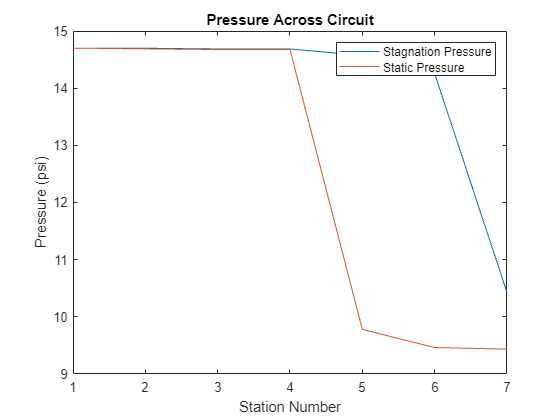


%% Plotting Pressures and Velocities
P0=[P0_inlet P0_honey P0_screen P0_contract P0_ts P0_diff P0_screen_debris];
P=[P_inlet P_honey P_screen P_contract P_ts P_diff P_screen_debris];
V=[V_Inlet2TS V_Inlet2TS V_Inlet2TS V_Inlet2TS V_req V_diff V_screen_debris];
figure (1)
plot(P0)
hold on
plot(P)
xlabel 'Station Number'
ylabel 'Pressure (psi)'
title 'Pressure Across Circuit'

% ylim([0 15])
legend 'Stagnation Pressure' 'Static Pressure'
hold off

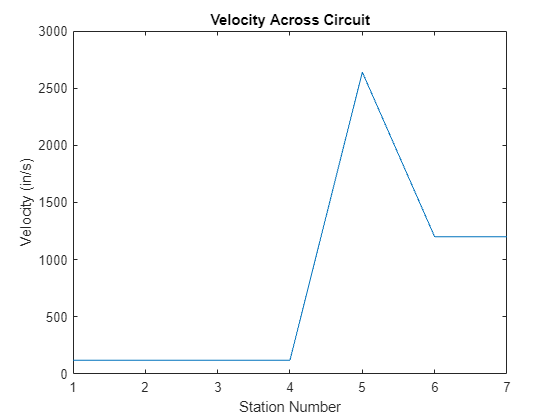

figure (2)
plot(V)
xlabel 'Station Number'
ylabel 'Velocity (in/s)'
title 'Velocity Across Circuit'

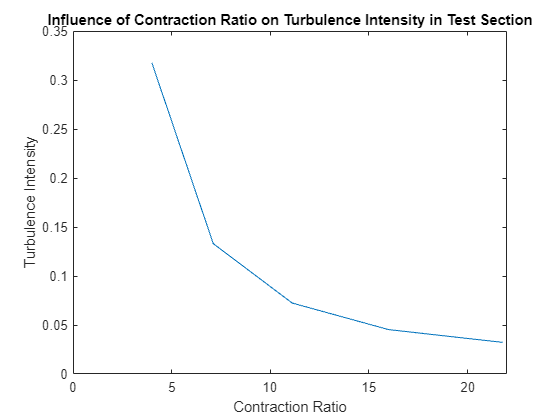


%% Sensitivity Analysis
CR_2screens=[21.7778 16 11.1111 7.1111 4];
TI_CR=[0.0323 0.0453 0.0724 0.133 0.3174];
n_CR21=[1 2 3 4 5];
TI_n=[0.0551 0.0323 0.015 0.0061 0.0022];
figure (3)
plot(CR_2screens,TI_CR)
xlabel 'Contraction Ratio'
ylabel 'Turbulence Intensity'
title 'Influence of Contraction Ratio on Turbulence Intensity in Test Section'
xlim([0 22])

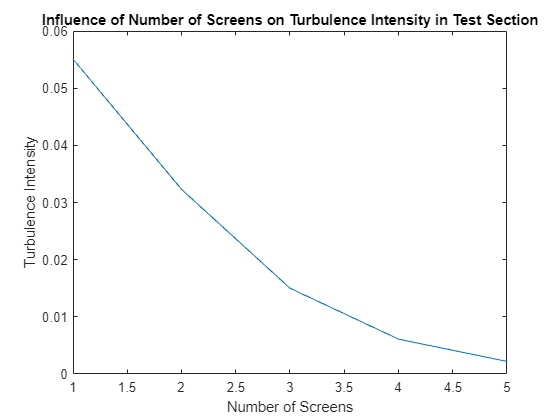

figure (4)
plot(n_CR21,TI_n)
xlabel 'Number of Screens'
ylabel 'Turbulence Intensity'
title 'Influence of Number of Screens on Turbulence Intensity in Test Section'